**Μέρος Β**

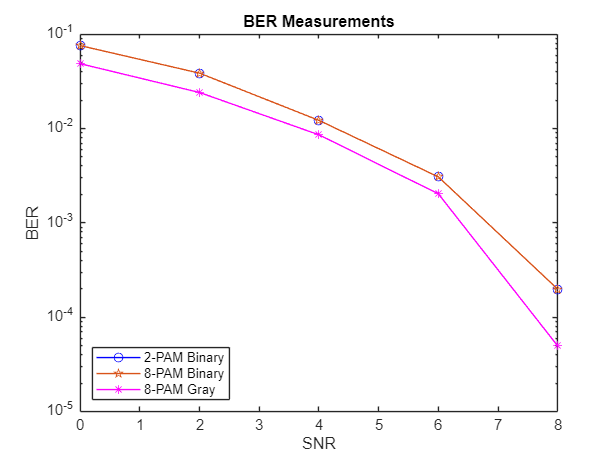


 function y = source(Lb)
 bits = [0 1];
 y = randsrc(1, Lb, bits);
 end

 function symbols = mapper(symbols_order, signal, M)
 size = log2(M);
 % matrix that contains the symbols that will be produced
 val_decimal = zeros(1, length(signal)/size);
 for i = 1:length(val_decimal)
 % calculate the indexes in every iteration in order to get
 % each time every log2(M) bits from the signal matrix
 start_index = (i-1) * size + 1;
 end_index = i * size;
 % transform every log2(M) bits to the corresponding symbol
 value = bi2de(signal(start_index:end_index), 'left-msb');
 % add to the symbols matrix
 val_decimal(i) = value;
 end
 % using the matlab's function pammod to specify the type of code
 % mapping (gray or binary) that will be applied
 symbols = real(pammod(val_decimal, M, 0, symbols_order));
 end

 function sm = modulator(symbols)
 % initialize the time units needed
 Tsymbol = 4 * 10^(-6);
 fc = 2.5 * 10^6;
 Tsample = 10^(-7);
 % rectangular pulse
 g = sqrt(2/Tsymbol);
 % initialize sampling
 samples = Tsymbol / Tsample;
 sm = zeros(samples*length(symbols), 1);
 t = (1:samples) * Tsample;
 for i = 1:length(symbols)
 s = symbols(i) * g * cos(2*pi*fc*t);

 start_index = (i-1) * samples + 1;
 end_index = i * samples;
 sm(start_index:end_index) = s;
 end
 end

 % apply noise using matlab's function
 function noise = AWGN(sm, SNR)
 noise = awgn(sm, SNR, 'measured');
 end

 function rt = demodulator(received)
 % initialize the time units needed
 Tsymbol = 4 * 10^(-6);
 fc = 2.5 * 10^6;
 Tsample = 10^(-7);
 % rectangular pulse
 g = sqrt(2/Tsymbol);
 samples = Tsymbol / Tsample;
 rt = zeros(length(received)/samples, 1);
 t = (1:samples) * Tsample;
 for i = 1:length(rt)
 start_index = (i-1) * samples + 1;
 end_index = i * samples;
 temp_y = received(start_index:end_index).*g.*cos(2*pi*fc*t)';
 rt(i) = sum(temp_y) * Tsample;
 end
 end

 function signal = demapper(symbols_order, symbols, M)
 size = log2(M);
 % specifies the type of coding applied to the binary words
 val_decimal = pamdemod(symbols, M, 0, symbols_order);
 signal = zeros(1, length(symbols)/size);
 for i = 1:length(val_decimal)
 start_index = (i-1) * size + 1;
 end_index = i * size;
 % converts the integers to binary

 value = de2bi(val_decimal(i), size, 'left-msb');
 signal(start_index:end_index) = value;
 end
 end
 %Ερωτήμα 2
 Lb = 20232;
 source_stream = source(Lb);
 SNRs = 0:2:20;
 % 2-PAM and Bin coding
 M = 2;
 symbols_order = 'bin';
 symbols = mapper(symbols_order, source_stream, M);
 sm = modulator(symbols);
 BERs1 = zeros(1, length(SNRs));
 for j = 1:length(SNRs)
 SNR1 = SNRs(j);
 noise = AWGN(sm, SNR1);
 rt = demodulator(noise);
 source_output = demapper(symbols_order, rt, M);
 BERs1(j) = sum(source_stream - source_output~=0)/Lb;
 end
 % ----------------------------------------------------------
  % 8-PAM and Bin coding
 M = 8;
 symbols_order = 'bin';
 symbols = mapper(symbols_order, source_stream, M);
 sm = modulator(symbols);
 BERs1 = zeros(1, length(SNRs));
 for j = 1:length(SNRs)
 SNR1 = SNRs(j);
 noise = AWGN(sm, SNR1);
 rt = demodulator(noise);
 source_output = demapper(symbols_order, rt, M);
 BERs1(j) = sum(source_stream - source_output~=0)/Lb;
 end
 % ----------------------------------------------------------
% 8-PAM and Gray coding
 M = 8;
 symbols_order = 'gray';
 symbols = mapper(symbols_order, source_stream, M);
 sm = modulator(symbols);
 BERs2 = zeros(1, length(SNRs));
 for j = 1:length(SNRs)
 SNR2 = SNRs(j);
 noise = AWGN(sm, SNR2);
 rt = demodulator(noise);
 source_output = demapper(symbols_order, rt, M);
 BERs2(j) = sum(source_stream - source_output~=0)/Lb;
 end
 figure()
 sml1 = semilogy(SNRs, BERs1, '-ob');
 hold on;
 sml2 = semilogy(SNRs, BERs1, '-p');
 hold on;
 sml3 = semilogy(SNRs, BERs2, '-m*');
 hold off;
 title('BER Measurements')
 xlabel('SNR')
 ylabel('BER')

 legend([sml1(1) sml2(1) sml3(1)], {'2-PAM Binary ', '8-PAM Binary ','8-PAM Gray'}, 'Location', 'southwest','NumColumns', 1);

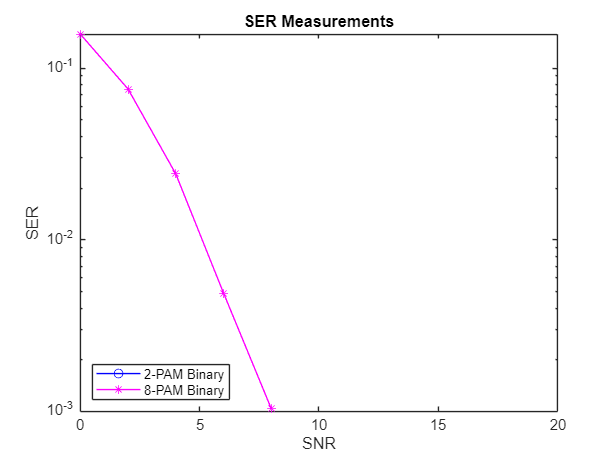

% Ερώτημα 3
 Lb = 20232;
 source_stream = source(Lb);
 SNRs = 0:2:20;
 symbols_order = 'bin';
 % 2-PAM and Bin coding
 M = 2;
 symbols = mapper(symbols_order, source_stream, M);
 sm = modulator(symbols);
 SERs1 = zeros(1, length(SNRs));
 for j = 1:length(SNRs)
 SNR1 = SNRs(j);
 noise = AWGN(sm, SNR1);
 rt = demodulator(noise);
 source_output = demapper(symbols_order, rt, M);
 symbols_found = mapper(symbols_order, source_output, M);
 SERs1(j) = sum(symbols - symbols_found~=0)/length(symbols_found);
 end
 % ----------------------------------------------------------
% 8-PAM and Bin coding
 M = 8;
 symbols = mapper(symbols_order, source_stream, M);
 sm = modulator(symbols);
 SERs2 = zeros(1, length(SNRs));
 for j = 1:length(SNRs)
 SNR2 = SNRs(j);
 noise = AWGN(sm, SNR2);
 rt = demodulator(noise);
 source_output = demapper(symbols_order, rt, M);
 symbols_found = mapper(symbols_order, source_output, M);
 SERs2(j) = sum(symbols - symbols_found~=0)/length(symbols_found);
 end
 figure()
 sml1 = semilogy(SNRs, SERs1, '-ob');
 hold on;
 sml2 = semilogy(SNRs, SERs2, '-m*');
 hold off;
 title('SER Measurements')
 xlabel('SNR')
 ylabel('SER')
 legend([sml1(1) sml2(1)], {'2-PAM Binary ', '8-PAM Binary'}, 'Location', 'southwest','NumColumns', 1);